Patm = 101325;       %atmospheric pressure in pa
Pdyn = 538;          %dynamic pressure of wind tunnel in pa
p = 1000;            %density of manometer fluid in kg/m3
g = 9.81;
rho = 1.225   ;       %density of air in kg/m3
d = 0.1  ;            %diameter of sphere in m
r = d/2;
S = 4*3.142* (r^2);
hc =  [0, 0.5, 1.7 3.4, 4.6, 4.6, 4.3, 4.2, 4.2, 4.2, 4.2, 4.2, 4.2, 4.4, 4.4, 4.4, 4.3, 4.4, 4.5, 4.6, 4.6, 3.1, 1.6, 0.5];   %manometer height for clean cylinder
HC = hc * 0.0254;    %manometer height in metres  
Ps = Patm - Pdyn;    %static pressure inside wind tunnel 

Ph = Patm - (p*g*HC) % STATIC PRESSURE CLEAN 

Ph =    1.0132e+05    1.012e+05    1.009e+05   1.0048e+05   1.0018e+05   1.0018e+05   1.0025e+05   1.0028e+05   1.0028e+05   1.0028e+05   1.0028e+05   1.0028e+05   1.0028e+05   1.0023e+05   1.0023e+05   1.0023e+05   1.0025e+05   1.0023e+05    1.002e+05   1.0018e+05   1.0018e+05   1.0055e+05   1.0093e+05    1.012e+05


Cp = (Ph - Ps)/Pdyn   % PRESSURE COEFFICIENT CLEAN 

Cp =             1      0.76843      0.21265     -0.57471      -1.1305      -1.1305     -0.99154     -0.94522     -0.94522     -0.94522     -0.94522     -0.94522     -0.94522      -1.0379      -1.0379      -1.0379     -0.99154      -1.0379      -1.0842      -1.1305      -1.1305     -0.43576      0.25896      0.76843




hc2 = [0, 0.3, 1.5, 2.6, 6.4, 5.8, 6.2, 5.1, 4.1, 4.1, 4.1, 4.1, 4.1, 4.1, 4.1, 4.1, 4.1, 4.4, 5.6, 5.7, 6.7, 2.7, 1.8, 0.5];
HC2 = hc2 * 0.0254 ;


Ph2 = Patm - (p*g*HC2) %STATIC PRESSURE DIRTY

Ph2 =    1.0132e+05   1.0125e+05   1.0095e+05   1.0068e+05        99730        99880        99780   1.0005e+05    1.003e+05    1.003e+05    1.003e+05    1.003e+05    1.003e+05    1.003e+05    1.003e+05    1.003e+05    1.003e+05   1.0023e+05        99930        99905        99656   1.0065e+05   1.0088e+05    1.012e+05


Cp2 = (Ph2 - Ps)/Pdyn   % PRESSURE COEFFICIENT DIRTY

Cp2 =             1      0.86106      0.30528     -0.20419      -1.9642      -1.6863      -1.8715      -1.3621     -0.89891     -0.89891     -0.89891     -0.89891     -0.89891     -0.89891     -0.89891     -0.89891     -0.89891      -1.0379      -1.5936      -1.6399      -2.1031      -0.2505      0.16633      0.76843




pos = 0:15:345;        %position at different angles 

V = [5 10 15 20 25 30 35 40 45 50 52 54 56 58 60];   % FLUID  VELOCITY


Af5 = mean ( [0.061 0.059 0.061 0.064 0.061 0.061 0.061 0.06 0.06 0.06 0.061 0.06 0.061 0.062 0.061 0.062 0.063 0.063 0.064 0.064]);



Af10 = mean ([0.267 0.269 0.267 0.268 0.263 0.269 0.269 0.264 0.27 0.264 0.27 0.263 0.269 0.268 0.261 0.263 0.252 0.263 0.258 0.258]);


Af15 = mean ([0.579 0.579 0.565 0.579 0.581 0.577 0.577 0.578 0.58 0.579 0.58 0.576 0.579 0.594 0.594 0.594 0.578 0.594 0.602 0.579]);



Af20 = mean([1.017 1.017 1.013 1.027 1.021 1.021 1.019 1.024 1.027 1.027 1.032 1.032 1.04 1.04 1.032 1.028 1.03 1.03 1.027 1.034]);


Af25 = mean ([1.581 1.614 1.62 1.572 1.572 1.572 1.553 1.56 1.583 1.581 1.583 1.567 1.576 1.576 1.565 1.559 1.554 1.548 1.553 1.552]);


Af30 = mean ([2.336 2.387 2.385 2.37 2.368 2.37 2.338 2.338 2.338 2.288 2.261 2.261 2.287 2.338 2.34 2.289 2.241 2.292 2.291 2.291]);


Af35 = mean ([3.39 3.39 3.359 3.227 3.359 3.362 3.403 3.403 3.422 3.403 3.408 3.408 3.408 3.379 3.41 3.402 3.376 3.348 3.351 3.302]);


Af40 = mean ([3.985 4.078 4.091 4.089 4.091 4.087 4.089 4.08 4.081 4.081 4.067 3.977 3.883 3.848 3.837 3.837 3.829 3.809 3.809 3.809]);


Af45 = mean ([4.923 4.923 4.92 4.913 4.913 4.913 4.937 4.937 4.979 4.97 4.988 4.988 4.988 4.966 4.96 4.96 4.887 4.957 4.964 4.961]);


Af50 = mean ([5.759 5.796 5.789 5.814 5.837 5.814 5.766 5.758 5.758 5.697 5.712 5.709 5.697 5.644 5.621 5.621 5.622 5.63 5.63 5.63]);


Af52 = mean ([5.76 5.733 5.733 5.705 5.42 5.424 5.424 5.416 5.403 4.764 4.754 4.754 4.725 4.729 4.72 4.729 4.683 4.708 4.697 4.673]);


Af54 = mean ([4.726 4.726 4.763 4.759 4.763 4.73 4.726 4.726 4.72 4.73 4.654 4.648 4.687 4.726 4.525 4.525 4.487 4.3 4.339 4.259 4.707 4.695 4.695 4.507 4.739 4.551 4.563 4.544 4.544 4.55 4.55 4.569 4.583 4.583 4.577 4.577 4.583 4.555 4.408 4.045]);


Af56 = mean ([4.354 4.313 4.325 4.325 4.396 4.464 4.396 4.333 4.39 4.39 4.396 4.333 4.333 4.396 4.665 4.716 4.715 4.653 4.703 4.653]);


Af58 = mean ([2.32 2.315 2.425 2.425 2.388 2.394 2.422 2.435 2.435 2.402 2.402 2.414 2.408 2.404 2.232 2.201 2.232 2.231 2.277 2.191]);


Af60 = mean ([1.917 1.645 1.645 1.702 1.702 1.645 1.701 1.752 1.752 1.695 1.752 1.718 1.695 1.661 1.739 1.683 1.551 1.752 2.144 1.655]);

AF = [Af5 Af10 Af15 Af20 Af25 Af30 Af35 Af40 Af45 Af50 Af52 Af54 Af56 Af58 Af60]

AF =       0.06145      0.26475       0.5822       1.0269        1.572       2.3204       3.3755       3.9728       4.9473       5.7152       5.0977       4.5911       4.4625       2.3477       1.7253




CD = (2* (AF))./(rho*(V.^2)*S)     % DRAG COEFFICIENT

CD =       0.12772      0.13757      0.13446       0.1334       0.1307      0.13397      0.14318      0.12902      0.12695      0.11879     0.097961     0.081812     0.073941     0.036263     0.024903


P2 = linspace(min(pos),max(pos),60)

P2 =             0       5.8475       11.695       17.542        23.39       29.237       35.085       40.932        46.78       52.627       58.475       64.322       70.169       76.017       81.864       87.712       93.559       99.407       105.25        111.1       116.95        122.8       128.64       134.49       140.34       146.19       152.03       157.88       163.73       169.58       175.42       181.27       187.12       192.97       198.81       204.66       210.51       216.36        222.2       228.05        233.9       239.75       245.59       251.44       257.29       263.14       268.98       274.83       280.68       286.53


z1 = interp1(pos,Cp,P2,'spline')

z1 =             1      0.94817      0.84724      0.69709      0.49764      0.24876    -0.045969     -0.36113      -0.6633     -0.91992      -1.0999      -1.1774      -1.1704      -1.1206      -1.0617      -1.0084     -0.97158     -0.95255     -0.94505     -0.94342     -0.94448     -0.94566     -0.94581     -0.94529     -0.94458      -0.9445     -0.94593     -0.94785     -0.94639     -0.93903     -0.93544     -0.95096     -0.98914      -1.0285      -1.0461      -1.0434      -1.0377      -1.0402      -1.0415      -1.0292      -1.0065     -0.99171     -0.99907      -1.0218      -1.0475      -1.0682      -1.0824      -1.0909      -1.1057      -1.1432


z2 = interp1(pos,Cp2,P2,'spline')

z2 =             1       1.0846      0.97628      0.75787      0.51209       0.3217      0.23306     0.076606     -0.39337      -1.1763      -1.8588      -2.0449      -1.8528      -1.6725      -1.7307       -1.855      -1.8277      -1.6212      -1.3506      -1.1157     -0.95066     -0.87404     -0.87211     -0.89709     -0.90753     -0.90329     -0.89747     -0.89681     -0.89856     -0.89952      -0.8993     -0.89883      -0.8987     -0.89884     -0.89905     -0.89913     -0.89887     -0.89831     -0.89836     -0.89996     -0.90155     -0.89917     -0.89877     -0.95188      -1.1208       -1.378      -1.5765      -1.5973       -1.565      -1.7042


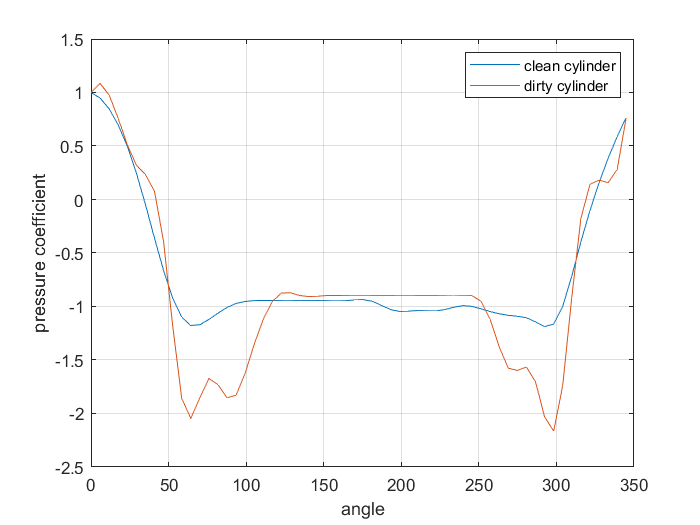

plot (P2, z1, P2, z2)
xlabel ('angle')
ylabel ('pressure coefficient')
legend ({'clean cylinder', 'dirty cylinder'} )

grid on 


Len = 0.1;                                                   
miu = (1.81*10^-5);        % dynamic viscosity of fluid                    

Rey = ((V *rho *Len)/miu)     %  REYNOLDS NUMBER                      

Rey =         33840        67680   1.0152e+05   1.3536e+05    1.692e+05   2.0304e+05   2.3688e+05   2.7072e+05   3.0456e+05    3.384e+05   3.5193e+05   3.6547e+05   3.7901e+05   3.9254e+05   4.0608e+05


Q1 = linspace(min(Rey),max(Rey),60)

Q1 =         33840        40149        46458        52767        59076        65385        71694        78004        84313        90622        96931   1.0324e+05   1.0955e+05   1.1586e+05   1.2217e+05   1.2848e+05   1.3479e+05   1.4109e+05    1.474e+05   1.5371e+05   1.6002e+05   1.6633e+05   1.7264e+05   1.7895e+05   1.8526e+05   1.9157e+05   1.9788e+05   2.0419e+05   2.1049e+05    2.168e+05   2.2311e+05   2.2942e+05   2.3573e+05   2.4204e+05   2.4835e+05   2.5466e+05   2.6097e+05   2.6728e+05   2.7359e+05    2.799e+05    2.862e+05   2.9251e+05   2.9882e+05   3.0513e+05   3.1144e+05   3.1775e+05   3.2406e+05   3.3037e+05   3.3668e+05   3.4299e+05


y1 = interp1(Rey,CD,Q1,'spline')

y1 =       0.12772      0.13149      0.13423      0.13606      0.13712      0.13755      0.13747      0.13704      0.13637      0.13561      0.13488      0.13433      0.13401      0.13385      0.13375      0.13364      0.13343      0.13304      0.13251      0.13193      0.13136      0.13087      0.13055      0.13047      0.13072      0.13139      0.13257      0.13434      0.13666      0.13913      0.14134      0.14286      0.14326       0.1422      0.13991      0.13687      0.13355      0.13045      0.12804       0.1265      0.12576      0.12568      0.12614      0.12705      0.12814      0.12877      0.12822      0.12578      0.12072       0.1125


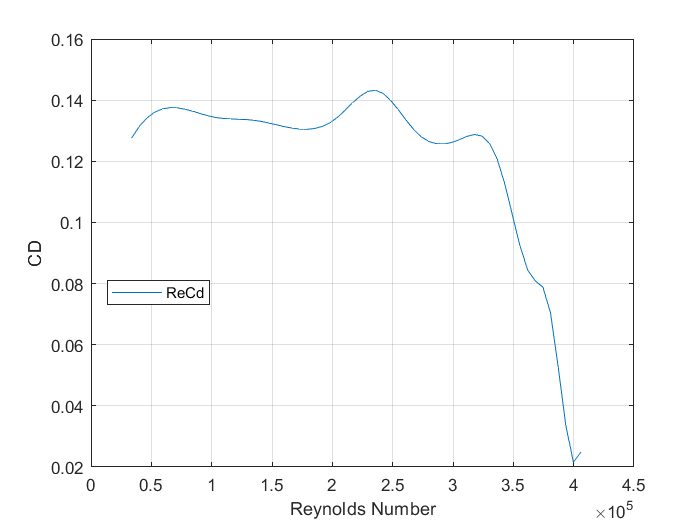

plot (Q1,y1)
xlabel ('Reynolds Number')
ylabel ('CD')
legend ('ReCd','Location','best')
grid on 



C = 0.093025            ;          % crossectional area of wind tunnel in m2
ds = (0.809 * ((S/C)^1.5));    % solid bockage
dw = ((1/4)* CD * (S/C)) ;    % wake blockage 
d = (ds + dw)             ;    % blockage factor 


V2 = (V.*(1 + d) )  %corrected free stream velocity

V2 =        5.8479       11.704       17.552       23.401       29.246       35.103       40.981       46.788       52.629       58.442       60.688       62.948       65.243       67.388       69.654



CD2 = (2* (AF))./(rho*(V2.^2)*S) % CORRECTED DRAG COEFFICIENT

CD2 =      0.093369      0.10042     0.098195     0.097439     0.095504      0.09785      0.10444     0.094302     0.092815     0.086951     0.071921     0.060205     0.054475     0.026863     0.018478



Rey2 = ((V2 *rho *Len)/miu) 

Rey2 =         39579        79213   1.1879e+05   1.5838e+05   1.9794e+05   2.3758e+05   2.7736e+05   3.1666e+05   3.5619e+05   3.9553e+05   4.1073e+05   4.2603e+05   4.4156e+05   4.5608e+05   4.7142e+05



Q2 = linspace(min(Rey2),max(Rey2),60)

Q2 =         39579        46898        54217        61537        68856        76175        83494        90814        98133   1.0545e+05   1.1277e+05   1.2009e+05   1.2741e+05   1.3473e+05   1.4205e+05   1.4937e+05   1.5669e+05   1.6401e+05   1.7133e+05   1.7865e+05   1.8596e+05   1.9328e+05    2.006e+05   2.0792e+05   2.1524e+05   2.2256e+05   2.2988e+05    2.372e+05   2.4452e+05   2.5184e+05   2.5916e+05   2.6648e+05    2.738e+05   2.8112e+05   2.8843e+05   2.9575e+05   3.0307e+05   3.1039e+05   3.1771e+05   3.2503e+05   3.3235e+05   3.3967e+05   3.4699e+05   3.5431e+05   3.6163e+05   3.6895e+05   3.7627e+05   3.8359e+05   3.9091e+05   3.9822e+05


y2 = interp1(Rey2,CD2,Q2,'spline')

y2 =      0.093369      0.09605        0.098     0.099312      0.10008       0.1004      0.10037      0.10007     0.099603     0.099063     0.098542     0.098135     0.097893     0.097769     0.097701     0.097628     0.097488     0.097228     0.096865     0.096452      0.09604     0.095681     0.095427     0.095334     0.095461     0.095871     0.096623     0.097778     0.099347       0.1011      0.10275      0.10398      0.10452      0.10407      0.10266      0.10062     0.098281     0.095983     0.094062     0.092753     0.092027     0.091811     0.092031     0.092615     0.093457     0.094163     0.094187     0.092982     0.089999     0.084711


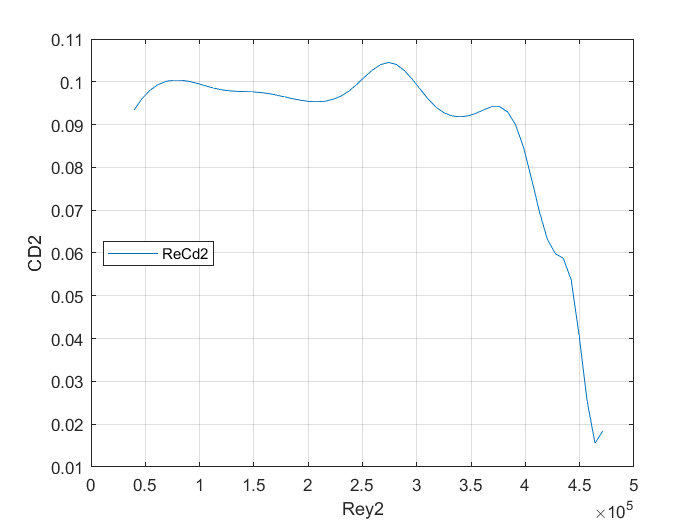

plot (Q2,y2)
xlabel ('Rey2')
ylabel ('CD2')
legend('ReCd2','Location','best')
grid on 



Vcrit = 45  

Vcrit =     45


REcr = ((Vcrit *rho *Len)/miu) %critical reynolds number

REcr =    3.0456e+05


T= (1.25 * (385000/REcr )-1.25) %Turbulence level 

T =       0.33016






Q3 = linspace(min(Rey),max(Rey),60)

Q3 =         33840        40149        46458        52767        59076        65385        71694        78004        84313        90622        96931   1.0324e+05   1.0955e+05   1.1586e+05   1.2217e+05   1.2848e+05   1.3479e+05   1.4109e+05    1.474e+05   1.5371e+05   1.6002e+05   1.6633e+05   1.7264e+05   1.7895e+05   1.8526e+05   1.9157e+05   1.9788e+05   2.0419e+05   2.1049e+05    2.168e+05   2.2311e+05   2.2942e+05   2.3573e+05   2.4204e+05   2.4835e+05   2.5466e+05   2.6097e+05   2.6728e+05   2.7359e+05    2.799e+05    2.862e+05   2.9251e+05   2.9882e+05   3.0513e+05   3.1144e+05   3.1775e+05   3.2406e+05   3.3037e+05   3.3668e+05   3.4299e+05


Q4 = linspace(min(Rey2),max(Rey2),60)

Q4 =         39579        46898        54217        61537        68856        76175        83494        90814        98133   1.0545e+05   1.1277e+05   1.2009e+05   1.2741e+05   1.3473e+05   1.4205e+05   1.4937e+05   1.5669e+05   1.6401e+05   1.7133e+05   1.7865e+05   1.8596e+05   1.9328e+05    2.006e+05   2.0792e+05   2.1524e+05   2.2256e+05   2.2988e+05    2.372e+05   2.4452e+05   2.5184e+05   2.5916e+05   2.6648e+05    2.738e+05   2.8112e+05   2.8843e+05   2.9575e+05   3.0307e+05   3.1039e+05   3.1771e+05   3.2503e+05   3.3235e+05   3.3967e+05   3.4699e+05   3.5431e+05   3.6163e+05   3.6895e+05   3.7627e+05   3.8359e+05   3.9091e+05   3.9822e+05


y3 = interp1(Rey,CD,Q3,'spline')

y3 =       0.12772      0.13149      0.13423      0.13606      0.13712      0.13755      0.13747      0.13704      0.13637      0.13561      0.13488      0.13433      0.13401      0.13385      0.13375      0.13364      0.13343      0.13304      0.13251      0.13193      0.13136      0.13087      0.13055      0.13047      0.13072      0.13139      0.13257      0.13434      0.13666      0.13913      0.14134      0.14286      0.14326       0.1422      0.13991      0.13687      0.13355      0.13045      0.12804       0.1265      0.12576      0.12568      0.12614      0.12705      0.12814      0.12877      0.12822      0.12578      0.12072       0.1125


y4 = interp1(Rey2,CD2,Q4,'spline')

y4 =      0.093369      0.09605        0.098     0.099312      0.10008       0.1004      0.10037      0.10007     0.099603     0.099063     0.098542     0.098135     0.097893     0.097769     0.097701     0.097628     0.097488     0.097228     0.096865     0.096452      0.09604     0.095681     0.095427     0.095334     0.095461     0.095871     0.096623     0.097778     0.099347       0.1011      0.10275      0.10398      0.10452      0.10407      0.10266      0.10062     0.098281     0.095983     0.094062     0.092753     0.092027     0.091811     0.092031     0.092615     0.093457     0.094163     0.094187     0.092982     0.089999     0.084711


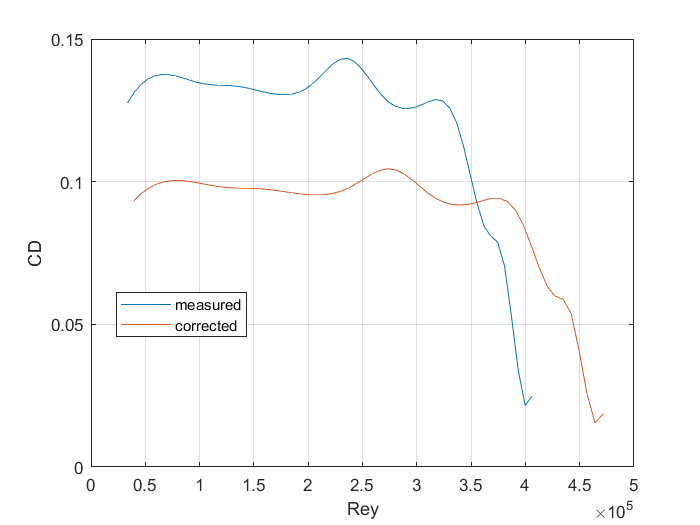

plot (Q3, y3, Q4, y4)
xlabel ('Rey')
ylabel ('CD')
legend({'measured', 'corrected'},'Location','best')
grid on